# **Final Group Project **- Allie Hearn and Rex Aledia

# *Coupled flow and saline intrusion in a coastal aquifer (Bakker 2016)*

[Walkthrough Video](https://youtu.be/IK0_BMGKsfM)

## Introduction

        Ground water makes up about 30% of the world’s freshwater. Since most of the remaining 70% is frozen, groundwater is the primary source of drinking water for many$\ldotp^1$ It is relied on by one-third of the United States population$\ldotp^3$ Groundwater is accessed by drilling wells below the water table into layers of permeable rock, called aquifers. This water source is not infinite, however. High rates of water pumping can deplete the aquifer and overtime, lower the water table. This leads to wells running dry or,  in coastal regions, being replaced with saltwater$\ldotp^2$

	When the freshwater in an aquifer is replaced over time by saltwater from the ocean, it is called saltwater intrusion. Saltwater intrusion is a major issue for coastal regions that rely on groundwater for drinking water. Pumping freshwater from aquifers directly leads to saltwater intrusion, as the ocean moves inland in order to replace the freshwater that is being taken. Increasing the rate of pumping also increases the rate at which saltwater intrusion happens$\ldotp^4$ For a long time, this has been a difficult problem to optimize. It is not just a challenge for humans. Saltwater intrusion can have an impact on the environment as well by damaging ecosystems reliant on having freshwater available$\ldotp^2$ 

	For over 75 years now, scientists have been working on models to help us understand factors that impact saltwater intrusion and the rate at which it happens$\ldotp^1$ Models can help us make better choices in regard to water pumping by predicting the impacts of different water resource decisions. Making good decisions will help us to both protect the environment and to keep coastal aquifers as a resource to us as drinking water$\ldotp^2$

        In order to more easily create models of saltwater intrusion, scientists have come up with many different approximations to simplify the equations involved.  The model presented here combines three of these different approximations. The first is the Dupuit approximation, developed in the late 1800s. This approximation assumes that groundwater flow is horizontal in order to neglect the resistance to vertical flow within the aquifer. With this assumption, the water table is flat and groundwater is hydrostatic$\ldotp^5$ 

	This model also makes use of the Boussinesq approximation which ignores density in order to simplify flow equations$\ldotp^6$ In order to use this approximation, one must assume that the density difference between freshwater and saltwater is relatively small. The third approximation assumes that the freshwater and saltwater are immiscible, meaning they do not mix together. This approximation ignores diffusion and dispersion between the two liquids, In order for this approximation to be reasonable, the time period over which the model is run must be relatively short. 

In addition to these major ones, a couple minor assumptions are made. It is assumed that the viscosity of both liquids are equal and that the aquifer is isotropic. 

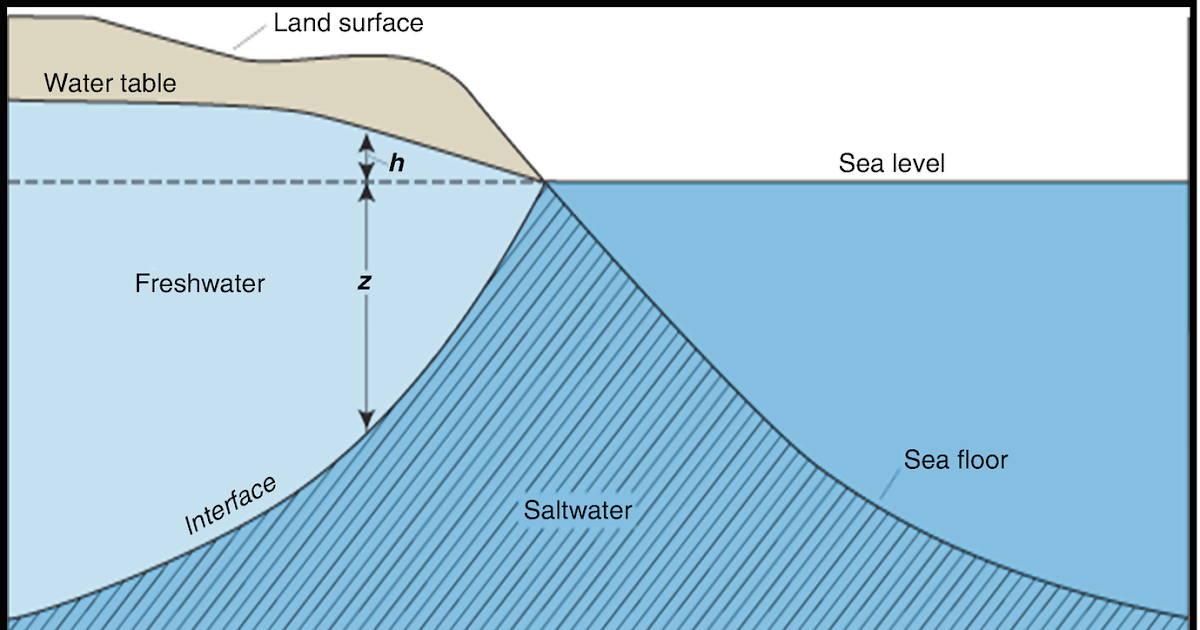

*Figure I: Diagram of the freshwater-saltwater interface with parameters h and z. *

## Derivation of Equations

        This model consists of two equations. The first equation defines one-dimensional interface flow in a single aquifer. The derivation of this equation starts with Darcy’s law, which describes the flow of a fluid through a porous medium$\ldotp^7$


$$q_x =-k\frac{\partial \phi }{\partial x}$$


$q_x$ represents the discharge in the x direction, k is the hydraulic conductivity of freshwater, and x shows how the freshwater head, 𝜙, changes in the x direction. The freshwater head is the elevation relative to a baseline point that freshwater rises in a well drilled into an aquifer. The position of the freshwater head is directly related to the position of the freshwater-saltwater interface. The freshwater head can be defined with a piecewise function using the Dupuit approximation. 


$$\phi =h,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;z\ge \zeta$$



$$\phi =h+v_s \left(\zeta -z\right),\;\;z\le \zeta$$


‘h’ is the head in the freshwater zone which is typically the height difference between sealevel and the water table, $v_s$ is the dimensionless density difference defined by $v_s =\frac{\left(\rho_s -\rho_f \right)}{\rho_f }$, and $\zeta$ is the vertical elevation of the freshwater-saltwater interface relative to sealevel. 

Combining the equation from Darcy’s law and the definition of the freshwater head, we get


$$q_x =-k\frac{\partial h}{\partial x},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;z\ge \zeta$$



$$q_x =-k\frac{\partial h}{\partial x}-k\frac{\partial \zeta }{\partial x},\;\;z\le \zeta$$


Next, the discharge vector is defined. The discharge vector is the integral of qx with respect to z from the bottom of the saturated aquifer to the top. The result is


$$Q_x =-k\left(z_t -z_b \right)\frac{\partial h}{\partial x}-kv_s \left(z_t -z_b \right)\frac{\partial \zeta }{\partial x}$$


Substituting in the definition of transmissivity ($T=k\left(z_t -z_b \right)$) and 'salt' transmissivity ($\tau =kv_s \left(z_t -z_b \right)$), the equation becomes


$$Q_x =-T\frac{\partial h}{\partial x}-\tau \frac{\partial \zeta }{\partial x}$$


Applying the Boussinesq approximation, we replace the mass balance equation with a volume balance equation, introducing N, the infiltration of salwater, and S, the storage coefficient.

$\frac{\partial Q_x }{\partial x}=N-S\frac{\partial h}{\partial x}$                           (volume balance equation)

Finally, taking the derivative of the discharge vector gives the final equation for one-dimensional interface flow in a single aquifer.

$\frac{\partial }{\partial x}\left(T\frac{\partial h}{\partial x}\right)=-N+S\frac{\partial h}{\partial t}-\frac{\partial }{\partial x}\left(\tau \frac{\partial \zeta }{\partial x}\right)$                                              (1)

        The second equation of the model describes the movement of the freshwater-saltwater interface. To derive it, we start with the vertically integrated flux in the saltwater zone. Similar to above, $q_x$ is integrated with respect to z, but this time the interval is from the bottom of the aquifer to $\zeta$, the elevation of the interface.  The resulting equation with the trasmissivity definitions substituted in is


$$Q_x^s =\frac{-\tau }{v_s }\frac{\partial h}{\partial x}-\tau \frac{\partial \zeta }{\partial x}$$


Using the equation for the continuity of flow in the saltwater zone where n is the effective porosity, taking the derivative of the salt discharge yields the second equation of the model. 

$\frac{\partial }{\partial x}\left(\tau \frac{\partial \zeta }{\partial x}\right)=n\frac{\partial \zeta }{\partial t}-\frac{\partial }{\partial x}\left(\frac{\tau }{v_s }\frac{\partial h}{\partial x}\right)$                                                     (2)

For the boundary conditions of our model, a uniform flow towards the coast of 0.1 ${\mathrm{m}}^2$/d is established, corresponding to a constant head and interface height at the coastline (x=0). For the initial conditions, an arbitrary square root function was used to approximate the initial position of the interface as seen in the original study.

## Numerical Methods

    To numerically solve this model consisting of a system of PDEs, we utilized a centered finite difference scheme to discretize in space. This method allowed us to evaluate the second derivatives in space for both the freshwater head and interface position. For discretization in time, both Forward Euler and Crank-Nicholson were used. By setting up the solver like this, it behaves similarly to a time-dependent diffusion equation as discussed in class. The many parameters present in each equation also serve similar functions as the diffusion number, which helps to conceptualize the numerical stability of the model. We can evaluate how stable the model will be based on Von-Neumann method for Forward Euler, wherein the diffusion number (or similar constants for this model C1, C2, C3, C4) should be less than or equal to 0.5 to maintain numerical stability. In contrast, the Crank-Nicholson method is unconditionally stable. By utilizing both methods, we can evaluate the stability of the model along different timescales.

## Foward Euler Method

#### Parameters

k = 2;          % hydraulic conductivity (m/d)
n = 0.1;        % effective porosity
S = 0.2;        % storage coefficient (?)
N = -0.0001;    % infiltration of freshwater (?)
H = 45;         % aquifer thickness (m)
zb = -45;       % bottom of aquifer (m)
zt = 0;         % top of aquifer (m)
L = 1000;       % length of cross-section (m)
W = 1;          % width of cross-section (m)
vs = 0.025;     % dimensionless density
x_ditch = 590;  % ditch position (m)
x_coastline = 0;% coastline position (m)

T = k*(zt-zb);  % transmissivity (m^2/d)
tau = vs*T;     % salt transmissivity (m^2/d)

dx = 5;        % gridspace size (m)
xi = 0;         % initial x (m)
xf = 1000;      % final x (m)
xs = xi:dx:xf;  % vector of gridspaces
nx = length(xs);% # of gridspaces

dt = 0.01;       % timestep size (yr)
ti = 0;         % initial time (yr)
tf = 50;       % final time (yr)
ts = ti:dt:tf;  % vector of timesteps
nt = length(ts);% # of timesteps

% matrix solving constants
C1 = T*dt/(S*dx^2);
C2 = tau*dt/(S*dx^2);
C3 = tau*dt/(n*dx^2);
C4 = tau*dt/(n*vs*dx^2);

max_C = max([C1, C2, C3, C4]);
if max_C > 0.5
    error('Time step dt is too large. CFL condition violated.');
end

if N > k * H * vs
    warning('Infiltration rate exceeds expected range for stability.');
end

#### Pre-Allocation, Initial Conditions

head_sol = zeros(nx,nt);    % solution matrix for freshwater he
zeta_sol = zeros(nx,nt);    % solution matrix for interface position

Q_IC = 0.1;                 % Uniform flow towards the coast (m^2/d)
zeta_IC = -Q_IC / (k * vs); % interface position at t = 0 (m)
head_IC = Q_IC / k;         % freshwater head at t = 0 (m)

zeta_initial = zeta_IC*sqrt(xs);    % IC vector

% Assign IC to solution vector
zeta_sol(:, 1) = zeta_initial;
head_sol(:,1) = head_IC;

#### Create solver matrices, Boundary Conditions

headM1 = spdiags([-C1.*ones(nx,1),(1-2*C1).*ones(nx,1),C1.*ones(nx,1)],-1:1,nx,nx);  % head matrix (for solving head)
zetaM1 = spdiags([-C2.*ones(nx,1),-2*C2.*ones(nx,1),C2.*ones(nx,1)],-1:1,nx,nx);     % interface matrix (for solving head)
headM2 = spdiags([-C4.*ones(nx,1),-2*C4.*ones(nx,1),C4.*ones(nx,1)],-1:1,nx,nx);     % head matrix (for solving interface)
zetaM2 = spdiags([-C3.*ones(nx,1),(1-2*C3).*ones(nx,1),C3.*ones(nx,1)],-1:1,nx,nx);  % interface matrix (for solving interface)

N_S = (N/S).*ones(nx,1); % source term vector
N_S(1) = 0; % maintain boundary conditions

zeta_BC = -2;               % interface position at x = 0 (m)
head_BC = 0.05;             % freshwater head at x = 0 (m)

head_sol(1,1) = head_BC;    % assign head BC (for just t = 0)
zeta_sol(1,1) = zeta_BC;    % assign interface BC (for just t = 0)

% preseve head BC for all x = 0
headM1(1,1) = 1;
headM1(1,2:end) = 0;
zetaM1(1,:) = 0;

% preserve interface BC for all x = 0
zetaM2(1,1) = 1;
zetaM2(1,2:end) = 0;
headM2(1,:) = 0;

% Gallery discharge
Q = -0.005;
x_gallery = round((x_ditch / 1000) * nx);  % index of gallery position in grid

Q_total = Q / (S * W);  % Distribute source evenly
N_S(max(1, x_gallery-1):min(nx, x_gallery+50)) = Q_total / (9 * dx);

#### Run model

% Run the model
for j = 1:nt - 1

    % Apply the updated Q to the source term
    N_S(max(1, x_gallery-1):min(nx, x_gallery+50)) = Q_total / (9 * dx);

    % Update the solution matrices
    head_sol(:, j + 1) = headM1 * head_sol(:, j) + zetaM1 * zeta_sol(:, j) + N_S;
    zeta_sol(:, j + 1) = zetaM2 * zeta_sol(:, j) + headM2 * head_sol(:, j);

    zeta_sol(1, j + 1) = zeta_BC;
    head_sol(1, j + 1) = head_BC;
end


#### Plot

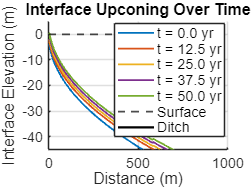

figure; hold on;

% Set plot properties
xlabel('Distance (m)', 'FontSize', 14);
ylabel('Interface Elevation (m)', 'FontSize', 14);
title('Interface Upconing Over Time', 'FontSize', 16);

% Use a colormap
colormap(parula);
colors = lines(6); % Set a consistent palette for 6 lines

% Plot selected transient states with legend
selected_steps = round(linspace(2, nt, 5)); % Select 5 timesteps evenly spaced
for idx = 1:length(selected_steps)
    step = selected_steps(idx);
    plot(xs, zeta_sol(:, step), 'Color', colors(idx, :), 'LineWidth', 1.5, ...
         'DisplayName', sprintf('t = %.1f yr', ts(step)));
end

% legend
legend('show', 'Location', 'best', 'FontSize', 12);

% Grid and limits
grid on;
ylim([zb 5]);
xlim([0 1000]);
set(gca, 'FontSize', 12);

h1 = yline(0, 'k--', 'LineWidth', 1.5);
h1.DisplayName = 'Surface';
x1 = 590;      % x-coordinate of the first point
y1 = 0;      % y-coordinate of the first point
x2 = 590;     % x-coordinate of the second point
y2 = -10;      % y-coordinate of the second point

% Plot the line segment
h2 = plot([x1, x2], [y1, y2], 'k-', 'LineWidth', 2);  % 'r-' for a red solid line
h2.DisplayName = 'Ditch';

hold off;

## Crank-Nicholson Method

#### Parameters

k = 2;          % hydraulic conductivity (m/d)
n = 0.1;        % effective porosity
S = 0.1;        % storage coefficient
N = 0.001;      % infiltration of freshwater
H = 45;         % aquifer thickness (m)
zb = -45;       % bottom of aquifer (m)
zt = 0;         % top of aquifer (m)
L = 1000;       % length of cross-section (m)
W = 1;          % width of cross-section (m)
vs = 0.025;     % dimensionless density
x_ditch = 590;  % ditch position (m)
x_coastline = 0;% coastline position (m)

% Derived parameters
T = k * (zt - zb); % transmissivity (m^2/d)
tau = vs * T;      % salt transmissivity (m^2/d)

dx = 1;            % grid space size (m)
xi = 0;            % initial x (m)
xf = 1000;         % final x (m)
xs = xi:dx:xf;     % vector of grid spaces
nx = length(xs);   % number of grid spaces

dt = 0.01;         % timestep size (yr)
ti = 0;            % initial time (yr)
tf = 100;          % final time (yr)
ts = ti:dt:tf;     % vector of timesteps
nt = length(ts);   % number of timesteps

% matrix constants for Crank-Nicholson scheme
C1 = T * dt / (2 * S * dx^2);
C2 = tau * dt / (2 * S * dx^2);
C3 = tau * dt / (2 * n * dx^2);
C4 = tau * dt / (2 * n * vs * dx^2);

% Construct matrix coefficients for Crank-Nicholson
A1 = spdiags([-C1 * ones(nx, 1), (1 + 2 * C1) * ones(nx, 1), -C1 * ones(nx, 1)], -1:1, nx, nx);
B1 = spdiags([C1 * ones(nx, 1), (1 - 2 * C1) * ones(nx, 1), C1 * ones(nx, 1)], -1:1, nx, nx);

A2 = spdiags([-C2 * ones(nx, 1), (1 + 2 * C2) * ones(nx, 1), -C2 * ones(nx, 1)], -1:1, nx, nx);
B2 = spdiags([C2 * ones(nx, 1), (1 - 2 * C2) * ones(nx, 1), C2 * ones(nx, 1)], -1:1, nx, nx);

A3 = spdiags([-C3 * ones(nx, 1), (1 + 2 * C3) * ones(nx, 1), -C3 * ones(nx, 1)], -1:1, nx, nx);
B3 = spdiags([C3 * ones(nx, 1), (1 - 2 * C3) * ones(nx, 1), C3 * ones(nx, 1)], -1:1, nx, nx);

A4 = spdiags([-C4 * ones(nx, 1), (1 + 2 * C4) * ones(nx, 1), -C4 * ones(nx, 1)], -1:1, nx, nx);
B4 = spdiags([C4 * ones(nx, 1), (1 - 2 * C4) * ones(nx, 1), C4 * ones(nx, 1)], -1:1, nx, nx);


#### Pre-Allocation, Initial Conditions

head_sol = zeros(nx, nt);
zeta_sol = zeros(nx, nt);

Q_IC = 0.1;                  % Initial condition for flow
zeta_IC = -Q_IC / (k * vs);  % Interface position at t=0 (m)
head_IC = Q_IC / k;          % Freshwater head at t=0 (m)

zeta_initial = zeta_IC * sqrt(xs);
zeta_sol(:, 1) = zeta_initial;
head_sol(:, 1) = head_IC;

#### Boundary Conditions

zeta_BC = -2;
head_BC = 0.05;

head_sol(1, 1) = head_BC;
zeta_sol(1, 1) = zeta_BC;

% Preserve boundary conditions for all x = 0
A1(1, 1) = 1;
B1(1, 1) = 1;
A2(1, 1) = 1;
B2(1, 1) = 1;
A3(1, 1) = 1;
B3(1, 1) = 1;
A4(1, 1) = 1;
B4(1, 1) = 1;

% Enforce boundary condition at x = L (e.g., zero flux)
A1(nx, nx-1) = -C1;
A1(nx, nx) = 1 + C1;
B1(nx, nx-1) = C1;
B1(nx, nx) = 1 - C1;

A2(nx, nx-1) = -C2;
A2(nx, nx) = 1 + C2;
B2(nx, nx-1) = C2;
B2(nx, nx) = 1 - C2;

A3(nx, nx-1) = -C2;
A3(nx, nx) = 1 + C2;
B3(nx, nx-1) = C2;
B3(nx, nx) = 1 - C2;

A4(nx, nx-1) = -C2;
A4(nx, nx) = 1 + C2;
B4(nx, nx-1) = C2;
B4(nx, nx) = 1 - C2;


#### Source Term

N_S = N * ones(nx, 1);  
N_S(1) = 0;

% Gallery discharge
Q = 0.005;
x_gallery = round((x_ditch / 1000) * nx);  % index of gallery position in grid

Q_total = Q / (S * W);  % Distribute source evenly
N_S(max(1, x_gallery-2):min(nx, x_gallery+2)) = Q_total / (10 * dx);


#### Run Model

for j = 1:nt - 1
    % Solve for head and interface using Crank-Nicholson scheme
    head_sol(:, j + 1) = A1 \ (B1 * head_sol(:, j) + N_S);
    zeta_sol(:, j + 1) = A2 \ (B2 * zeta_sol(:, j) + N_S);
    
    % Enforce boundary conditions at each time step
    zeta_sol(1, j + 1) = zeta_BC;
    head_sol(1, j + 1) = head_BC;
end

#### Plot

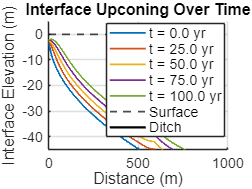

figure; hold on;

% Set plot properties
xlabel('Distance (m)', 'FontSize', 14);
ylabel('Interface Elevation (m)', 'FontSize', 14);
title('Interface Upconing Over Time', 'FontSize', 16);

% Use a colormap
colormap(parula);
colors = lines(6); % Set a consistent palette for 6 lines

% Plot selected transient states with legend
selected_steps = round(linspace(2, nt, 5)); % Select 5 timesteps evenly spaced
for idx = 1:length(selected_steps)
    step = selected_steps(idx);
    plot(xs, zeta_sol(:, step), 'Color', colors(idx, :), 'LineWidth', 1.5, ...
         'DisplayName', sprintf('t = %.1f yr', ts(step)));
end

% legend
legend('show', 'Location', 'best', 'FontSize', 12);

% Grid and limits
grid on;
ylim([zb 5]);
xlim([0 1000]);
set(gca, 'FontSize', 12);

h1 = yline(0, 'k--', 'LineWidth', 1.5);
h1.DisplayName = 'Surface';
x1 = 590;      % x-coordinate of the first point
y1 = 0;      % y-coordinate of the first point
x2 = 590;     % x-coordinate of the second point
y2 = -10;      % y-coordinate of the second point

% Plot the line segment
h2 = plot([x1, x2], [y1, y2], 'k-', 'LineWidth', 2);  % 'r-' for a red solid line
h2.DisplayName = 'Ditch';

hold off;

## Results

    We ran a few different simulations and varied methods, runtimes, and additional factors. First, we tried creating a simple model of saltwater intrusion into an aquifer using the Forward Euler method (Figure 2). It was run for a total time of 50 years with 12.5 year intervals. As expected, the model showed the saltwater-freshwater interface moving upwards and inland from the initial condition.

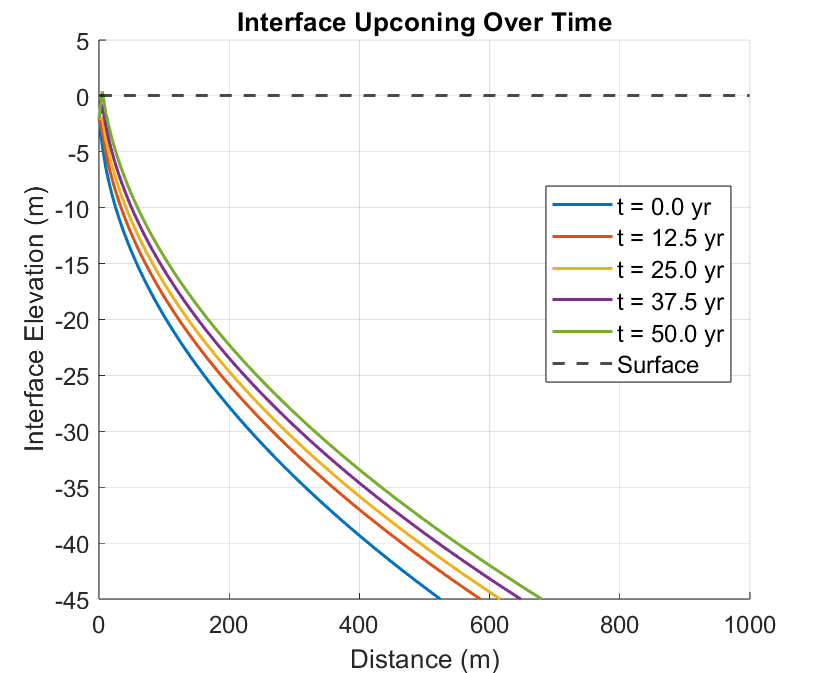

*Figure 2. Simulation of saltwater intrusion over 50 years using Forward Euler method.*

When trying to run the model for longer timescales, however, we ran into difficulty with numerical stability and maintaining the initial conditions. As show in Figure 3, as the interface moves away from its initial position, the starting point at x = 0 shifts up the y-axis. This creates an impossible scenario where the saltwater interface is above the ground. Because the matrix solving constants (diffusion numbers) were not all the same, and therefore not all dimensionless, there may have been some instability introduced with the interaction between them and the complexity of the model. Additionally, the timestep unit of years was not converted to days when calculating the constants, so they may be much larger than suggested. Again, this would lead to the Forward Euler method becoming unstable, as the diffusion number should be less than or equal to 0.5 for numerical stability.

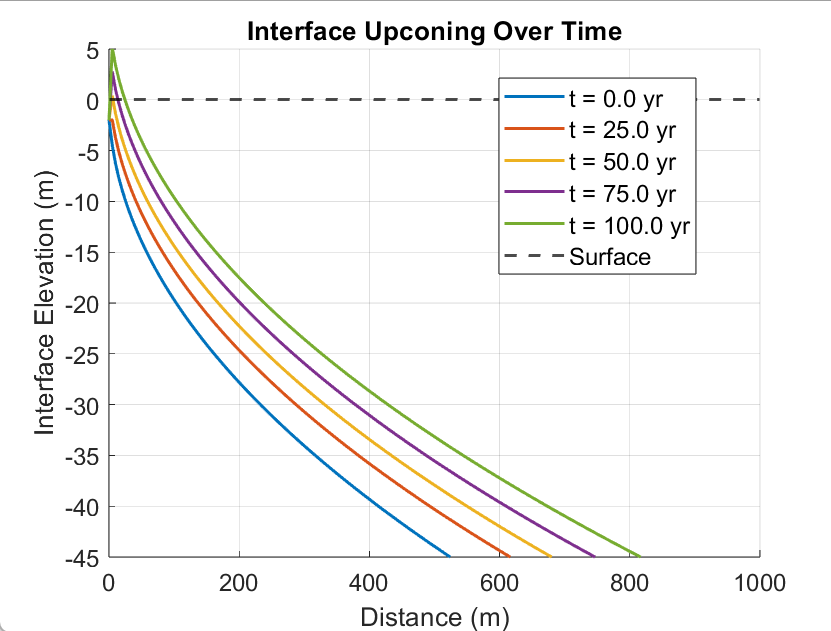

*Figure 3. Forward Euler method over a 100 year timescale. *

In an attempt to create a model that wouldn't shift up the y-axis with time, we also ran the simulation using the unconditionally stable Crank-Nicholson Method.. Using this method, we were able to sucessfully model the system over both shorter and longer timescales (Figures 4 & 5). The Crank-Nicholson method does a much better job of maintining a realistic model compared to the Forward Euler method, but it too starts to shift upwards over even longer timescales. Fortunately, this model is only meant to be run over short timescales as noted in the paper. 

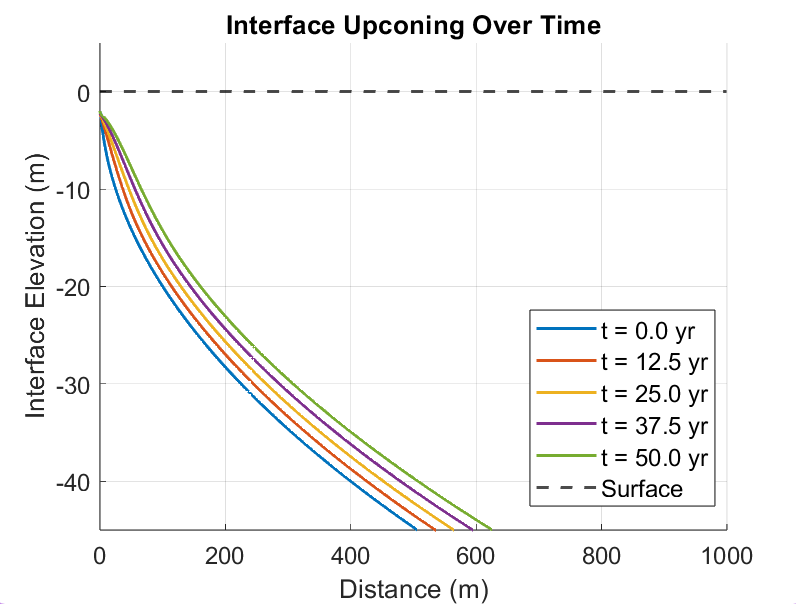

*Figure 4. Crank-Nicholson Method over 50-year timescale.*

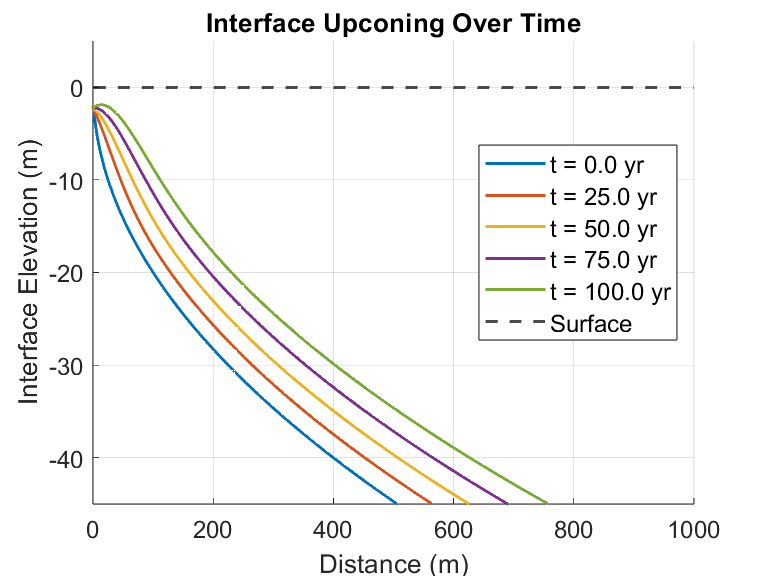

*Figure 5. Crank-Nicholson method over 100 year timescale. *

The model shown in the paper also includes a gallery at x = 590 that creates a localized change in the flow rate, since it would be pulling freshwater up towards the surface. The effect of this gallery on the saltwater-freshwater interface is to create a small knickpoint below where the gallery is (Figure 6).

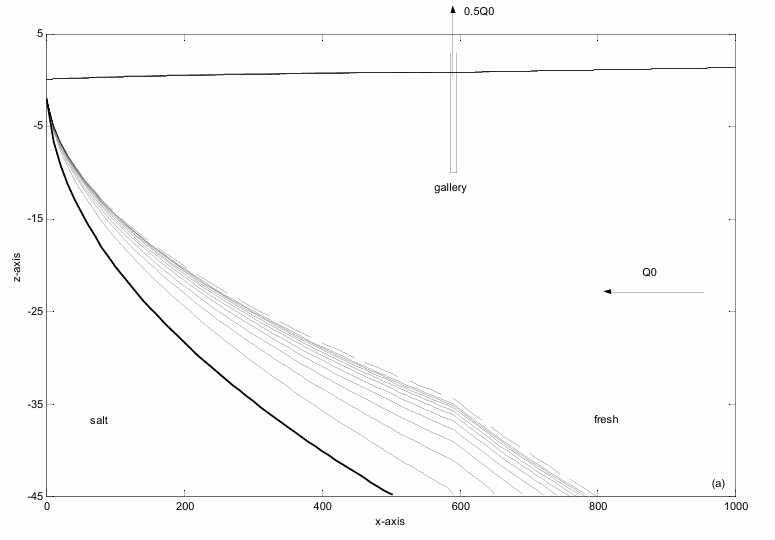

*Figure 6. Plot from paper including gallery (Bakker 2016).*

We attempted to include the gallery in our model using both methods. Since the Forward Euler limited how small we could make the grid spaces, it was difficult to make the effect localized while keeping the interface smooth (Figure 7). On the other hand, the Crank-Nicholson method created a much smoother knickpoint on the saltwater-freshwater interface (Figure 8).

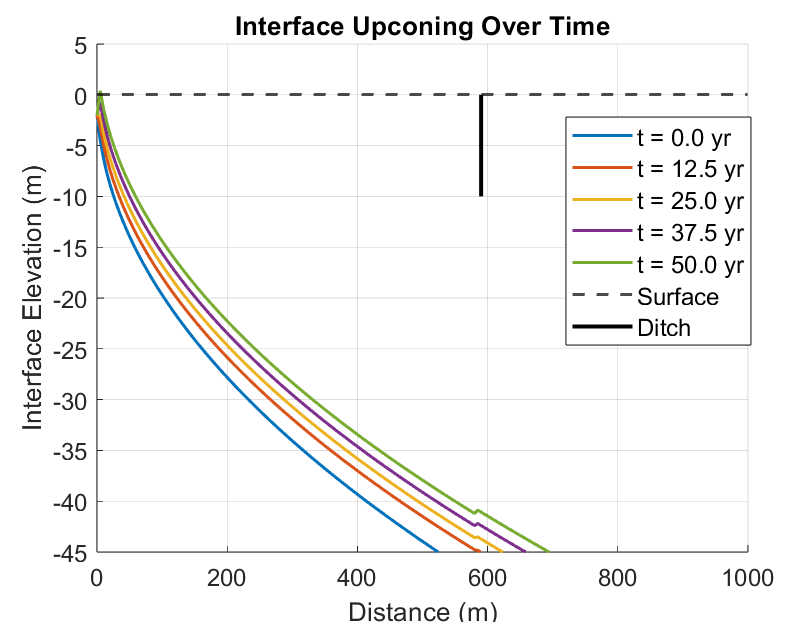

*Figure 7. Forward Euler method with gallery.*

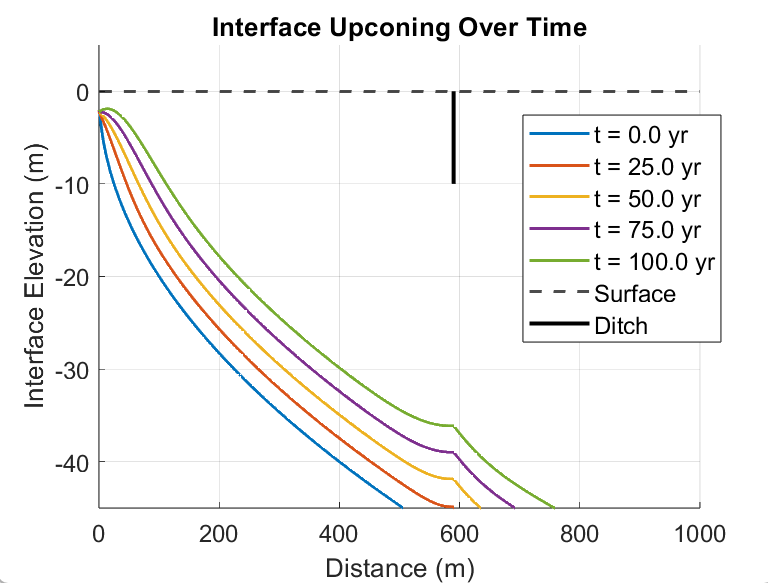

*Figure 8. Crank-Nicholson method with gallery.*

All things considered, the Crank-Nicholson method seemed to do a better job modeling saltwater intrusion into a coastal aquifer. It created a smoother interface with the gallery added and handled larger time scales better. Crank-Nicholson is implicit, as information is used from both the current and next timestep. Because of this, it is able to handle larger and longer timescales without blowing up. On the other hand, Forward Euler method is explicit, using information only from the current timestep. Because of this, larger timesteps are much more prone to becoming unstable.

This model might be improved by investigating the impacts of a time-dependent boundary condition at the coastline as a result of pumping, as suggested by the paper. We chose not to implement this in favor of improving the stability of the model through the use of different methods as discussed. However, a changing boundary condition might have significant impacts on the movement of the interface, especially if the rate of pumping is increased. Additionally, accounting for the difference between saltwater and freshwater densities (among the other assumptions amde in the model) may more accurately simulate real-world conditions. Because saltwater is denser, this difference may result in greater inland intrusion, pushing the interface further from the coastline.

Through these simulations, the imminence and impact of saltwater intrusion is made clear. Even over relatively short time periods (50 years), the interface moves inland and upward a considerable distance. With the addition of the pumping well, this effect is exacerbated. Improper drilling and use of wells in coastal aquifers can contaminate freshwater sources, so it is imperative that models like these are considered when accessing such resources. Understanding just how much and how fast the interface might move can inform decisions and help people protect these coastal aquifers.

## References

- Bear, J., Cheng, A.HD. (1999). Introduction. In: Bear, J., Cheng, A.HD., Sorek, S., Ouazar, D., Herrera, I. (eds) Seawater Intrusion in Coastal Aquifers — Concepts, Methods and Practices. Theory and Applications of Transport in Porous Media, vol 14. Springer, Dordrecht. [https://doi.org/10.1007/978-94-017-2969-7_1](https://doi.org/10.1007/978-94-017-2969-7_1)

- Costall, A.R., Harris, B.D., Teo, B. *et al.* Groundwater Throughflow and Seawater Intrusion in High Quality Coastal Aquifers. *Sci Rep* **10**, 9866 (2020). [https://doi.org/10.1038/s41598-020-66516-6](https://doi.org/10.1038/s41598-020-66516-6)

- “The Quality of the Nation’s Groundwater: U.S. Geological Survey.” *The Quality of the Nation’s Groundwater | U.S. Geological Survey*, Communications and Publishing, 21 Jan. 2015, www.usgs.gov/news/featured-story/quality-nations-groundwater. 

- “Saltwater Intrusion.” *Saltwater Intrusion | U.S. Geological Survey*, Water Resources Mission Area, 2 Mar. 2019, www.usgs.gov/mission-areas/water-resources/science/saltwater-intrusion

- “Dupuit–Forchheimer Assumption.” *Wikipedia*, Wikimedia Foundation, 26 Apr. 2016, en.wikipedia.org/wiki/Dupuit%E2%80%93Forchheimer_assumption. 

- “Boussinesq Approximation (Buoyancy).” *Wikipedia*, Wikimedia Foundation, 21 Oct. 2024, en.wikipedia.org/wiki/Boussinesq_approximation_(buoyancy). 

- “Darcy’s Law.” *Wikipedia*, Wikimedia Foundation, 15 Nov. 2024, en.wikipedia.org/wiki/Darcy%27s_law. 